close all;
clear all;
%% Load Data
load("data_save.mat");  % 'data' = [forcing_amp, forcing_freq, response_amp]

forcing_amp   = data(:, 1);  % dependent variable (what we predict)
forcing_freq  = data(:, 2);  % input
response_amp  = data(:, 3);  % input

X_data = [forcing_freq, response_amp]; % nx2
y_data = forcing_amp; %nx1

training_idx = randperm(length(y_data), 1)

training_idx = 41

addpath("GPR_FUNCS\");

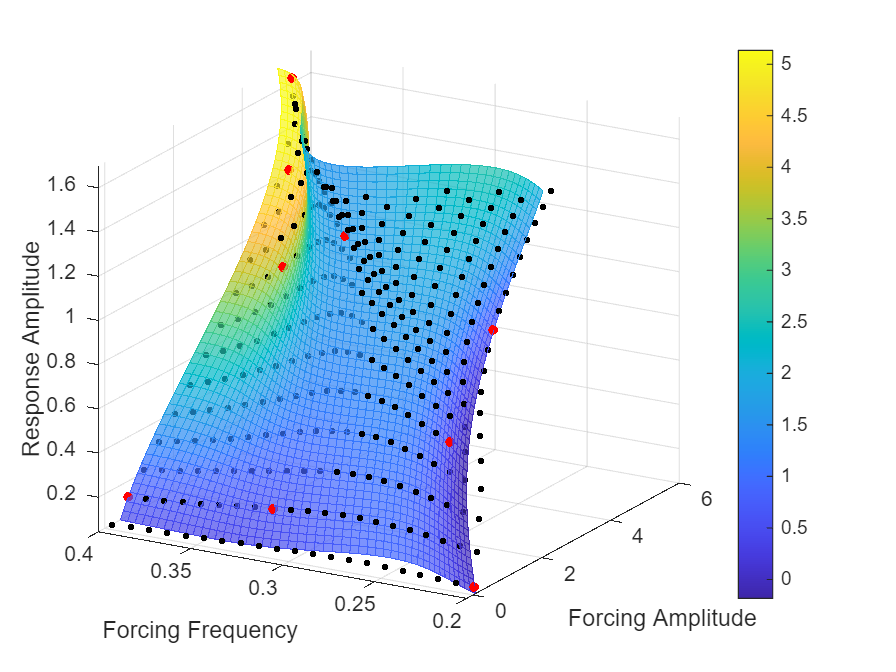

X_train = X_data(training_idx, :);
y_train = y_data(training_idx);

gpr_model = fitrgp(X_train, y_train, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

%% Generate Prediction Grid
freq_range = linspace(min(forcing_freq), max(forcing_freq), 50);
resp_range = linspace(min(response_amp), 1.7, 50);
[FF, RR] = meshgrid(freq_range, resp_range);  % RR: response amp, FF: forcing freq

% Predict forcing amplitude
X_query = [FF(:), RR(:)];  % input = [response_amp, forcing_freq]

% query model
[Y_pred, Y_std] = predict(gpr_model, X_query);
AA = reshape(Y_pred, size(RR));     % Forcing amp surface
STD = reshape(Y_std, size(RR));     % Confidence surface

%% PLOT
figure; hold on; grid on;
xlabel("Forcing Amplitude"); ylabel("Forcing Frequency"); zlabel("Response Amplitude");
zlim([min(response_amp), 1.7]);
surf_opt = struct("CData", AA, "FaceAlpha",0.7, "EdgeColor","interp");
surf(AA, FF , RR, surf_opt)
colorbar
scatter3(forcing_amp, forcing_freq, response_amp, 10, "filled", "k")
scatter3(forcing_amp(training_idx), forcing_freq(training_idx), response_amp(training_idx), 20, "filled", "r")
view(-60, 20)


% === Inputs you already have ===
% FF, RR (meshgrid), X_query = [FF(:), RR(:)]
% gpr_model  (fitrgp with 'ardsquaredexponential', Standardize=true)

vdim = 2;              % derivative along RR (column 2)
tau  = 0.05;           % e.g., threshold for |∂μ/∂v|
R    = 64;             % Monte-Carlo draws per candidate
weightMode = 'sigmaD'; % 'none' | 'sigmaD' | 'gain2'

% --- Build caches and baseline once ---
C     = gpr_build_caches(gpr_model, X_query, vdim);
Base  = gpr_baseline_fields(C);
p0    = soft_band_prob(Base.muD, Base.sigD, tau);  %#ok<NASGU> (if you want to visualize)

% --- Choose a candidate set ---
% Option A: all grid points (slow if many)
% Xcand = X_query;

% Option B: top-M variance points on the grid (common & fast)
Mpick = 100;
[~, idxv] = maxk(Base.varf, Mpick);
Xcand = X_query(idxv, :);

% --- Score candidates ---
scores = zeros(size(Xcand,1),1);
for i = 1:size(Xcand,1)
    xstar = Xcand(i,:);
    scores(i) = score_candidate_soft(xstar, C, Base, tau, R, weightMode);
end

% --- Pick best ---
[bestScore, bestIdx] = max(scores);
bestX = Xcand(bestIdx,:);

fprintf('Best candidate: [FF, RR] = [%.4g, %.4g],  E[Δ] = %.4g\n', bestX(1), bestX(2), bestScore);

Best candidate: [FF, RR] = [0.3347, 1.7],  E[Δ] = 0.003983



% (Optional) visualize gain and soft band for the best candidate
[~, det] = score_candidate_soft(bestX, C, Base, tau, R, weightMode);
MU  = reshape(Base.mu,  size(FF));
p0m = reshape(soft_band_prob(Base.muD, Base.sigD, tau), size(FF));
gM  = reshape(det.g, size(FF));

figure; 
subplot(3,1,1); imagesc(FF(1,:), RR(:,1), MU); axis xy; colorbar; title('\mu(u,v)');
hold on; plot(bestX(1), bestX(2), 'rx', 'LineWidth', 2); xlabel('FF'); ylabel('RR');

subplot(3,1,2); imagesc(FF(1,:), RR(:,1), p0m); axis xy; colorbar; title('p(|\partial\mu/\partial v|<\tau)');
hold on; plot(bestX(1), bestX(2), 'rx', 'LineWidth', 2);

subplot(3,1,3); imagesc(FF(1,:), RR(:,1), gM); axis xy; colorbar; title('gain g(x) at best x^\\star');
hold on; plot(bestX(1), bestX(2), 'rx', 'LineWidth', 2);


nbias = min(X_data, [], 1);
nscale = max(X_data,[],1);
nX_data = (X_data-nbias)./nscale;
nbestX = (bestX-nbias)./nscale;
[~, best_index] = min(sum(abs(nX_data - nbestX), 2))

best_index = 286

nextX = X_data(best_index, :)

nextX =     0.3300    1.7228


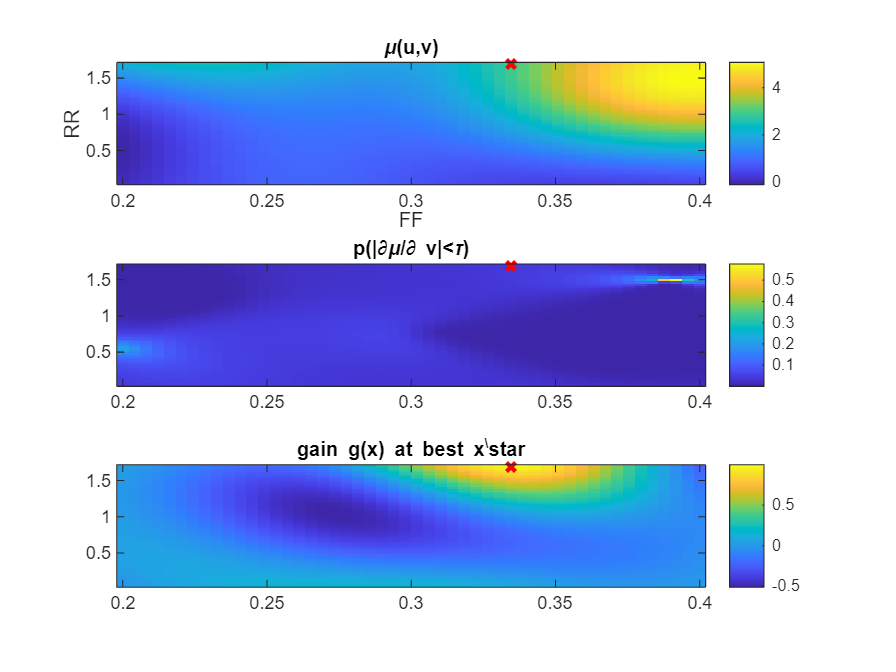

plot(nextX(1), nextX(2), 'gx', 'LineWidth', 2);

training_idx = [training_idx, best_index]

training_idx =     41     1    47   411   254   422   366   413    11   220   286
